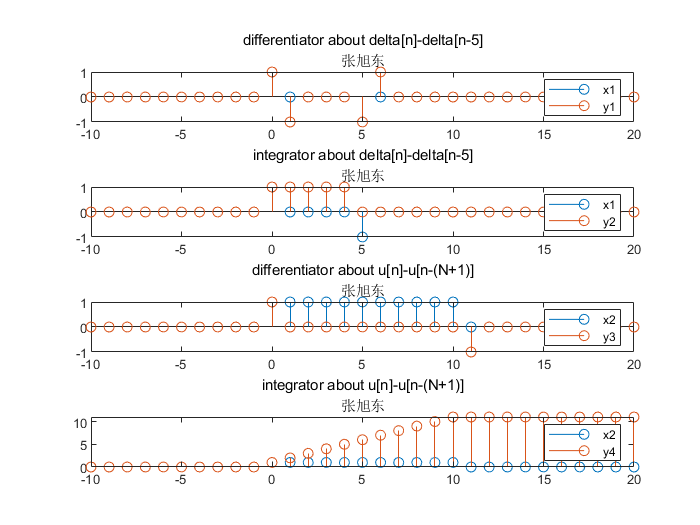

n=-10:1:20;
N=10;
x1=[zeros(1,10) 1 zeros(1,4) -1 zeros(1,15)];
y1=differentiator(x1);
y2=integrator(x1);
subplot(4,1,1);
stem(n,x1);hold on
stem(n,y1);legend('x1','y1');
title(['differentiator about delta[n]-delta[n-5]' newline '张旭东'])
subplot(4,1,2);
stem(n,x1);hold on
stem(n,y2);legend('x1','y2');
title(['integrator about delta[n]-delta[n-5]' newline '张旭东'])
u1=(n>=0);
u2=(n>=N+1);
x2=u1-u2;
y3=differentiator(x2);
y4=integrator(x2);
subplot(4,1,3);
stem(n,x2);hold on;
stem(n,y3);legend('x2','y3');
title(['differentiator about u[n]-u[n-(N+1)]' newline '张旭东'])
subplot(4,1,4);
stem(n,x2);hold on;
stem(n,y4);legend('x2','y4');
title(['integrator about u[n]-u[n-(N+1)]' newline '张旭东'])